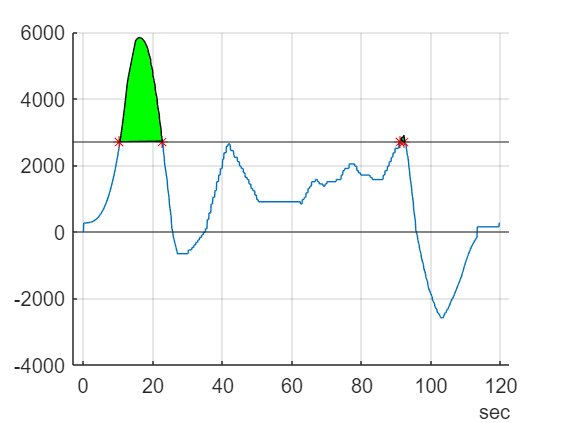

% mehr als eine Schnittstelle:

% for n = 1:length(CRset)
%     EBatPeak(n) = 0;
% 
%     while (ETOT * CRset(n) > EBatPeak)
%         inters(n) = inters(n) - 1;
%         [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters(n) inters(n)]);
%         xlin = round(xlin);
%         if(length(xlin) > 2)
% 
%             for i = 1:2:length(xlin)
% 
%                 EBatPeak(n) = EBatPeak + sum(CompData.Leistung(xlin(i):xlin(i+1))-inters(n))*const.dt;
% 
%             end
%         else
%             EBatPeak(n) = sum(CompData.Leistung(xlin(1):xlin(2))-inters(n))*const.dt;
%         end
% 
%         PBatPeak(n) = max(CompData.Leistung) - inters(n);
%         
%     end
% end

cla reset
% Berechnung der Gesamtfläche:
% Es wird das Matlab Package "Fast and Robust Curve Intersections" von
% Douglas Schwarz benötigt.

for i = 1:length(CompData.Strecke)
    if (CompData.Leistung(i) > 0)
        Etot(i,1) = CompData.Energie(i);
    else
        Etot(i,1) = 0;
    end
end
ETOT = sum(Etot);

inters = max(CompData.Leistung)-10; % the intersection line

EBatPeak = 0;

while (ETOT * CR/100 > EBatPeak)
    EBatPeak = 0;
    inters = inters - 1;
    [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters inters]);
    xlin = round(xlin);

    if(length(xlin) > 2)

        for i = 1:2:length(xlin)

            EBatPeak = EBatPeak + sum(CompData.Leistung(xlin(i):xlin(i+1))-inters)*const.dt;

        end
    else
        EBatPeak = sum(CompData.Leistung(xlin(1):xlin(2))-inters)*const.dt;
    end

%     if (ETOT * CR/100 < 0.999 * EBatPeak)
%         inters = inters + 1.5;
%         EBatPeak = 0;
%     end

end

PBatPeak = max(CompData.Leistung) - inters;

hold on
plot(CompData.time, CompData.Leistung)
for i = 1:2:length(xlin)
    plot(CompData.time(xlin(i)),ylin(i),'r*', CompData.time(xlin(i+1)), ylin(i+1),'r*')
    fill(CompData.time(xlin(i):xlin(i+1)), CompData.Leistung(xlin(i):xlin(i+1)), 'g')
end
yline(inters)
yline(0)
grid()

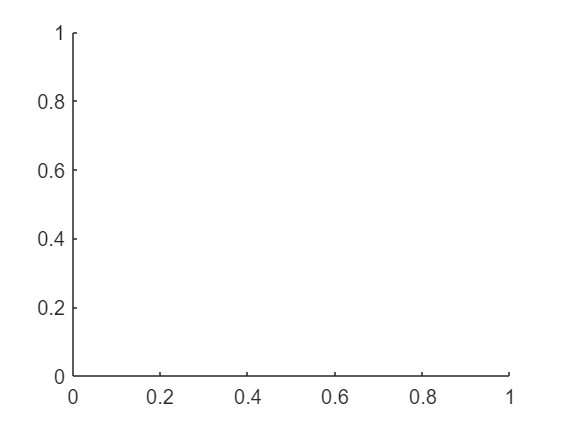

cla reset